OD=46.74*10^-3; %outer diameter [m]
ID=24.13*10^-3; %inner diameter [m]
HT=18.03*10^-3; %height [m]
Area= (OD-ID)/2*HT;
l_effective=pi*(OD+ID)/2;
I=10; %current 10A
Oersted=79.57747 % A/m

Oersted = 79.5775


$$%\mu =\frac{1}{\left(a+b{\left(H\right)}^c \right)}$$


a=0.01;
b=5.83e-6

b = 5.8300e-06

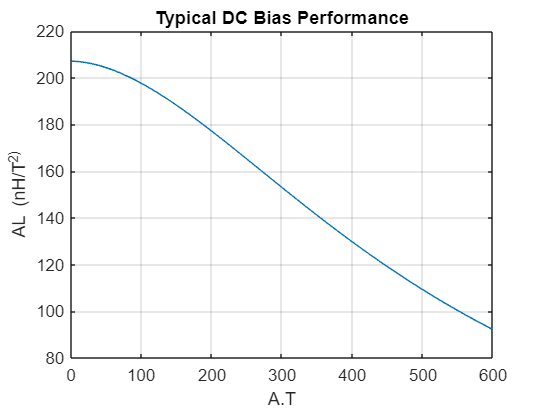

c=1.819;
mu_max=90;
mu_0=4*pi*10^-7;
AL_function=@(NI) 1./(a+b*(NI./(l_effective*Oersted)).^c)*mu_max/100*mu_0*Area/l_effective*10^9;
turns=linspace(0,60,200);
MMF=turns.*I;
AL=AL_function(MMF);
plot(MMF,AL)
grid on
title("Typical DC Bias Performance")
ylabel("AL (nH/T^2)")
xlabel("A.T")

L_desired=200*1000; % inductance [nH]
epsilon=10*1000; % tolerable error in inductance [nH]
max_iterations=20;
N=zeros(1,max_iterations);
A_L=zeros(1,max_iterations);
mmf=zeros(1,max_iterations);
for i=1:max_iterations
    mmf(i)=I*N(i);
    A_L(i)=AL_function(mmf(i));
    N_needed=sqrt(L_desired/A_L(i));
    A_L_new=AL_function(N_needed*I);
    L_new=A_L_new*N_needed^2;
    abs_error=abs(L_desired-L_new);
    if abs_error<epsilon
        break
    else
        N(i+1)=N_needed;
    end
end
N_determined=N_needed

N_determined = 38.1134

A_L_result=AL_function(N_needed*I);
L_designed=N_determined^2*A_L_result/1000 % uH

L_designed = 194.5436